## **HCP Maximum Variance explained by all Communication/Similarity Measures **

This script computes the maximum variance in FC (node-specific) explained by any of the 8 coupling measures for each individual and averages node-specific values across all individuals. It also plots the respective figure in the paper. 

**Before running ths script:**

- Run HCP_compute_coupling_measures

- Run  setup_data & example from visualization folder 

**1) Save all coefficients per node (All_Nodes_complete but with R^2 Values)** 

1.1) Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:1030
    x = final_r_all_HCP_1030_new{i,2};
    for j = 1:358
    Node_all_baseline_best_measures_HCP_r2{i,j} = x(j,:);
    end
end


1.2) Create cell containing information about all subjects and coupling measures per node

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 1030*8 matrix for each node)

n = size(Node_all_baseline_best_measures_HCP_r2,2);
All_Nodes_complete_baseline_best_measures_HCP_r2 = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_HCP_r2{j} = vertcat(Node_all_baseline_best_measures_HCP_r2{:,j});
end 

**2) Find the maximum value per row and keep it**

for i = 1:358
    node_values = All_Nodes_complete_baseline_best_measures_HCP_r2{1,i};

    for p = 1:1030
        individual_values = node_values(p,:);
        max_r2 = max(individual_values);
        Max_values_individuals_HCP(1,p) = max_r2;

    end
    Mean_per_node = mean(Max_values_individuals_HCP);

    Mean_values_across_all_nodes{1,i} = Mean_per_node;
end


**3) Convert cell to mat **

Mean_values_across_all_nodes_mat = cell2mat(Mean_values_across_all_nodes)

Mean_values_across_all_nodes_mat =     0.2315    0.1254    0.1915    0.2410    0.2415    0.2612    0.3101    0.2875    0.2573    0.0529    0.0659    0.0894    0.2489    0.1410    0.0922    0.2570    0.1274    0.1759    0.2910    0.3010    0.2949    0.2687    0.1451    0.1792    0.0667    0.0849    0.0880    0.0861    0.0966    0.0877    0.1095    0.0855    0.0995    0.1129    0.1125    0.2222    0.1100    0.0646    0.2424    0.2498    0.1486    0.1730    0.1361    0.1135    0.1097    0.1157    0.1528    0.0536    0.0890    0.1162


**4) Insert a 0 at Node 120 & 300**

a = Mean_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Mean_values_across_all_nodes_mat_360 = a

Mean_values_across_all_nodes_mat_360 =     0.2315    0.1254    0.1915    0.2410    0.2415    0.2612    0.3101    0.2875    0.2573    0.0529    0.0659    0.0894    0.2489    0.1410    0.0922    0.2570    0.1274    0.1759    0.2910    0.3010    0.2949    0.2687    0.1451    0.1792    0.0667    0.0849    0.0880    0.0861    0.0966    0.0877    0.1095    0.0855    0.0995    0.1129    0.1125    0.2222    0.1100    0.0646    0.2424    0.2498    0.1486    0.1730    0.1361    0.1135    0.1097    0.1157    0.1528    0.0536    0.0890    0.1162


ans = 0.3280

**5) Plot the Maximum Variance explained (across all subjects)**

Mean_values_across_all_nodes_mat_360(120) = NaN;
Mean_values_across_all_nodes_mat_360(300)= NaN;

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Mean_values_across_all_nodes_mat_360

dataVec =     0.2315    0.1254    0.1915    0.2410    0.2415    0.2612    0.3101    0.2875    0.2573    0.0529    0.0659    0.0894    0.2489    0.1410    0.0922    0.2570    0.1274    0.1759    0.2910    0.3010    0.2949    0.2687    0.1451    0.1792    0.0667    0.0849    0.0880    0.0861    0.0966    0.0877    0.1095    0.0855    0.0995    0.1129    0.1125    0.2222    0.1100    0.0646    0.2424    0.2498    0.1486    0.1730    0.1361    0.1135    0.1097    0.1157    0.1528    0.0536    0.0890    0.1162


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.3500]
    viewcMap: 1
     viewStr: 'all'


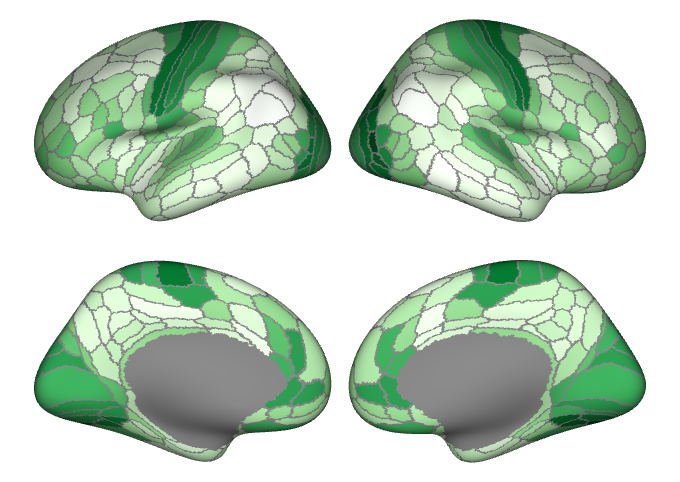

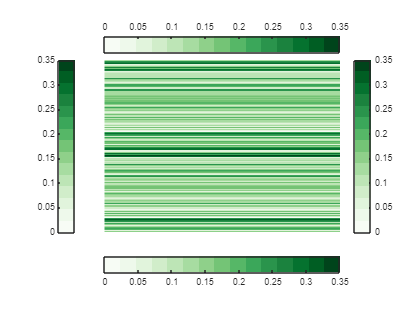

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(15,'Greens'),...
    'viewcMap',1, 'valRange', ([0 0.35]))